clc,clear,close all
I = imread('Fig0.tif');
I = tofloat(I);
% 定义2个空间滤波器
h1 = fspecial('average'); % 平滑滤波器
h2 = fspecial('sobel'); % 锐化滤波器
PQ = paddedsize(size(I)) % 用于计算图像FFT所用的填充尺寸

PQ =    512   512


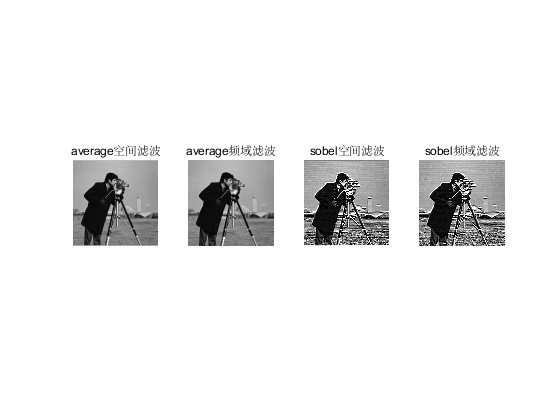

H1 = freqz2(h1,PQ(1), PQ(2)); % 空间滤波器转频域滤波器
H2 = freqz2(h2,PQ(1), PQ(2));
ifft1 = ifftshift(H1); % shift
ifft2 = ifftshift(H2);
% show results
subplot(141),imshow(imfilter(I,h1)),title('average空间滤波')
subplot(142),imshow(dftfilt(I,ifft1)),title('average频域滤波')
subplot(143),imshow(imfilter(I,h2)+I),title('sobel空间滤波')
subplot(144),imshow(dftfilt(I,ifft2)+I),title('sobel频域滤波')

clc,clear,close all
I = imread('Fig0.tif');
I = im2double(I); % 图像归一化		
M = 2*size(I,1), N = 2*size(I,2)

M = 512

N = 512

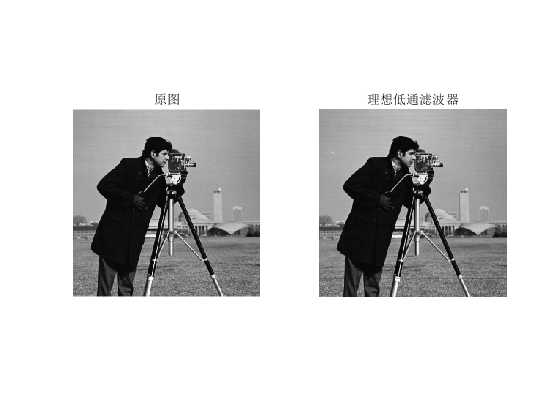

u = -M/2:(M/2-1);
v = -N/2:(N/2-1);
[U,V] = meshgrid(u, v);
D = sqrt(U.^2+V.^2);
% 理想低通滤波器
D0 = 255;
H1 = double(D<=D0);
J1 = fftshift(fft2(I, size(H1, 1), size(H1, 2)));
K1 = J1.*H1; % 时域图像转换为频域
L1 = ifft2(ifftshift(K1));
L1 = L1(1:size(I,1), 1:size(I, 2)); % 频域图像转换为时频
figure
subplot(1,2,1),imshow(I),title('原图')
subplot(1,2,2),imshow(L1),title('理想低通滤波器')

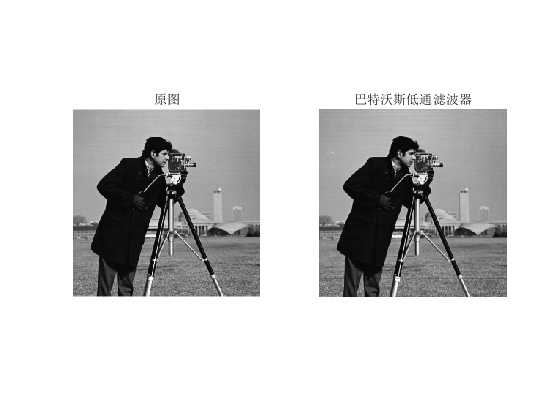

% 巴特沃斯低通滤波器
n = 10;
H2 = 1./(1+(D./D0).^(2*n));
J2 = fftshift(fft2(I, size(H2, 1), size(H2, 2))); % 时域图像转换为频域
K2 = J2.*H2;
L2 = ifft2(ifftshift(K2)); % 频域图像转换为时频         
L2 = L2(1:size(I,1), 1:size(I, 2));
figure
subplot(1,2,1),imshow(I),title('原图')
subplot(1,2,2),imshow(L2),title('巴特沃斯低通滤波器')

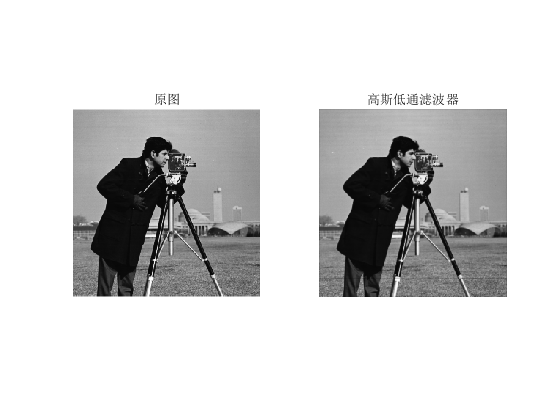

% 高斯低通滤波器
H3 = exp(-(D.^2)./(2*(D0.^2)));
J3 = fftshift(fft2(I, size(H3, 1), size(H3, 2))); % 时域图像转换为频域
K3 = J3.*H3;
L3 = ifft2(ifftshift(K3));            
L3=L3(1:size(I,1), 1:size(I, 2)); % 频域图像转换为时频
figure
subplot(1,2,1),imshow(I),title('原图')
subplot(1,2,2),imshow(L3),title('高斯低通滤波器')

clc,clear,close all
I = imread('Fig0.tif');
I = im2double(I); % 图像归一化		
M = 2*size(I,1), N = 2*size(I,2)

M = 512

N = 512

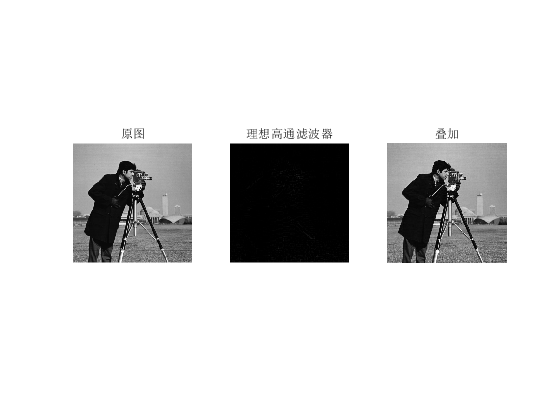

u = -M/2:(M/2-1);
v = -N/2:(N/2-1);
[U,V] = meshgrid(u, v);
D = sqrt(U.^2+V.^2);
% 理想高通滤波器
D0 = 255;
H1 = double(D>D0);
J1 = fftshift(fft2(I, size(H1, 1), size(H1, 2)));
K1 = J1.*H1; % 时域图像转换为频域
L1 = ifft2(ifftshift(K1));
L1 = L1(1:size(I,1), 1:size(I, 2)); % 频域图像转换为时频
figure
subplot(1,3,1),imshow(I),title('原图')
subplot(1,3,2),imshow(L1),title('理想高通滤波器')
subplot(1,3,3),imshow(L1+I),title('叠加')

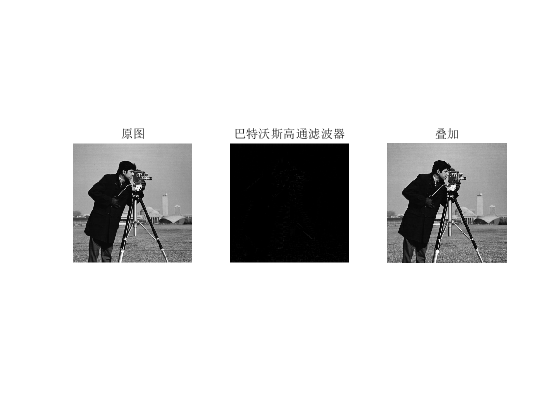

% 巴特沃斯高通滤波器
n = 6; % 滤波器的阶数
H2 = 1./(1+(D0./D).^(2*n));
J2 = fftshift(fft2(I, size(H2, 1), size(H2, 2)));   
% 时域图像转换为频域
K2 = J2.*H2;
L2 = ifft2(ifftshift(K2));   
% 频域图像转换为时频
L2 = L2(1:size(I,1), 1:size(I, 2));
figure
subplot(1,3,1),imshow(I),title('原图')
subplot(1,3,2),imshow(L2),title('巴特沃斯高通滤波器')
subplot(1,3,3),imshow(L2+I),title('叠加')

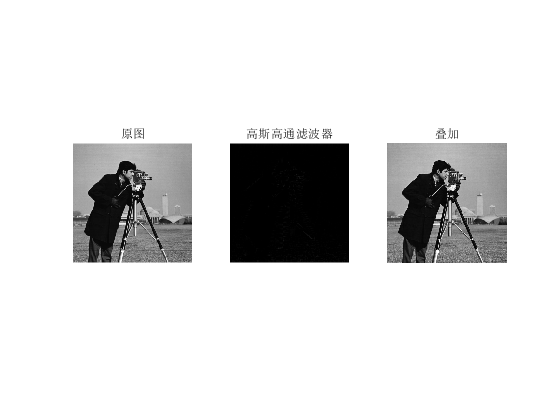

% 高斯高通滤波器
H3 = 1-exp(-(D.^2)./((D0.^2)));
J3 = fftshift(fft2(I, size(H3, 1), size(H3, 2)));   
% 时域图像转换为频域
K3 = J3.*H3;
L3 = ifft2(ifftshift(K3));            
% 频域图像转换为时频
L3 = L3(1:size(I,1), 1:size(I, 2));
figure
subplot(1,3,1),imshow(I),title('原图')
subplot(1,3,2),imshow(L2),title('高斯高通滤波器')
subplot(1,3,3),imshow(L2+I),title('叠加')